#  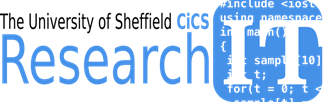                                      

# **Programming with Matlab: Developing and Testing Robust Code**

## Exercise 1:

We have written a simple program which simulates the motion under gravity of a rocket orbiting the earth and/or moon. This illustrates one method of developing an animation.Study the code in the folder matlab_examples/casestudies/mission-moon/code

Using the instructions below, run the code - observe an orbit of the satellite of the earth

pwd %need to be in the casestudies/mission-moon/code

ans = 'C:\Users\mike\proj\matlab-cic6007-2018\matlab_examples\casestudies\mission-moon\code'

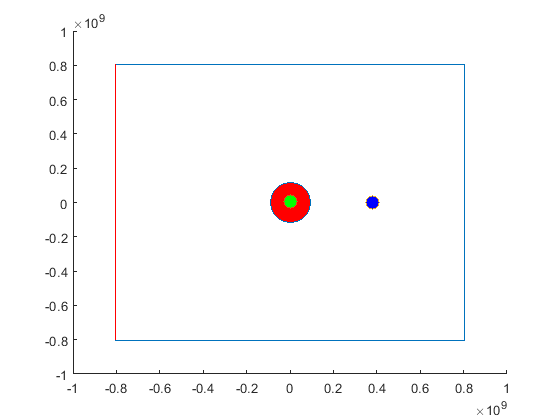

initrocket2themoon


%change the time step dt to 10
dt=10

% startrocketgraphics %enter this command from the matlab workbench command window
%playrocket2themoon


Run the code - observe an orbit of the satellite of the moon by loading the moonorbittest  data

In the case studies file use the code analyzer - and 

Run the reports and study the TODO/FIXME reports

Moon orbit test

load moonorbittest.mat

% startrocketgraphics %enter this command from the workbench command window
% playrocket2the moon


Now study the other versions of the code code-003-newdatastructures, code-004-functioncalls, code-005-tests

Study how the structure of the application has evolved through the addition of structures and function calls. Review the test scripts which we will run later.

## Exercise 2

Suppose that two different methods are used to read in vectors `pA` and `pB`. You can see that the vectors look identical, but how would you check for equality?

pA = [51.6461 78.1961 0.0004 72.7758 29.4412 15.5017 ]

pA =    51.6461   78.1961    0.0004   72.7758   29.4412   15.5017


pB = [51.6461 78.1961 0.0004 72.7758 29.4412 15.5017 ]

pB =    51.6461   78.1961    0.0004   72.7758   29.4412   15.5017


Create a variable named `check` which compares whether or not `pA` is equal to `pB` by using the `isequal` function.

%%TODO
check=

check = logical
   1


You have determined that the vectors are not equal, but which element, in particular, is the problem? Use the `==` operator to determine this.

This time, create a variable named `test` which compares each element of `pA` with each element of `pB`.

%%TODO
test=

test = 1×6 logical array
   1   1   1   1   1   1


## Exercise 3: Assert Functions

Write an `assert` statement that passes when the  difference of distance between the earth and moon and the constant dem ( `const.dem`) is less than the tolerance value of 

tol=50.2e6m

[https://en.wikipedia.org/wiki/Lunar_distance_(astronomy)](https://en.wikipedia.org/wiki/Lunar_distance_(astronomy))

addpath('../matlab_examples/casestudies/mission-moon/code-005-tests/')
load('moonorbittest.mat')
tol=50.2e6

tol = 50200000

const.dem

ans = 381500000

simdem=dist(state.xe,state.ye,state.xm,state.ym)

simdem = 3.8150e+08


%%TODO
assert(........)

Write an `assert` statement that passes when `const.dem` is equal to sim`dem`.

%%TODO
%assert(isequal(simdem,const.dem))

Simple Test

Create a variable `x` containing the value `3`.

test=[4 3 2 3 8]

test =      4     3     2     3     8


expect=[16  9  4  9 64];
f =@(x)(x-1).^2+5

f = function_handle with value:
    @(x)(x-1).^2+5


%TODO


Create a variable `xLoc` that uses `==` to perform an elementwise comparison between `x` and `test`.

%TODO
xLoc = .....

xLoc = 1×5 logical array
   0   1   0   1   0


Create the variable `xTest` which contains a value of `true`if `f(x)` is equal to `9` and `false` otherwise.

%TODO
xTest = .....

xTest = logical
   1


Use `assert` to test if `f(test)` is equal to `expect`.

%assert(isequal(f(test),expect))

Assertion failed.

Create a script that does the following:

- Create a variable named `x` containing a vector of 100 values between 0 and π.

- Create a variable named `y` that contains the square roots of all the values in `x`.

- Use `assert` to test the behavior of the `sqrt` function to determine if the output given in `y` is real.

%TODO script here
%% Test 1
% Create variable x
x = ....... ;

% Create y
y = .......  ;

% Test if result is real valued
assert(isreal(y))


**Info:** When this script is run, it should produce an error since the square root of a negative number is not a real value.

Modify the script so that `x` contains a vector of 100 values between -π and π.

%%TODO script here
%% Test 1
% Create variable x
x = linspace(-pi,pi);

% Create y
y = sqrt(x);

% Use an assert to Test if result is real valued
assert(isreal(y))


## Exercise 4: Practice running unit tests using run tests

## Task 1

Run the  section of code below.

Next put the code in a script named runroottest.m and use the command runroottest to run the tests

It will be necessary to fix the test below which is incomplete you may notice that after running the open script, one of the tests is incomplete. Fix the script runr`oottest` so that all the tests run to completion.

%% Positive roots are real
x = linspace(0,pi);
y = sqrt(x);
assert(isreal(y))

%% Negative roots are complex
z = linspace(-pi,pi);
y = sqrt(z);
assert(~isreal(y))

%% Sqrt(x) is smaller than x (if x > 1)
%TODO the line below is the missing line
x = .......;  %each section has its own workspace
y = x + 2;
z = sqrt(y);
assert(all(y > z))


## Task 2

Add the code below to a file called  `squareRootTestError`

Run the script `squareRootTestError` from the command line. An error is generated, but how much information do you get from the error message? And are the tests after where the error is generated run?

%% Positive roots are real
x = linspace(0,pi);
y = sqrt(x);
assert(isreal(y))

%% Negative roots are complex
z = linspace(-pi,pi);
y = sqrt(z);
assert(~isreal(y))

%% Law of universal linearity
x = linspace(0,pi);
y = linspace(1,42);
z1 = sqrt(x + y);
z2 = sqrt(x) + sqrt(y);
assert(isequal(z1,z2)) % <-- bad test!

%% Sqrt(x) is smaller than x (if x > 1)
x = linspace(0,pi);
y = x + 2;
z = sqrt(y);
assert(all(y > z))


**Info:** You may have noticed that the script stops execution once it encounters an error.

This time,run the script `squareRootTestError` so that all the tests are run and save the results in a variable with the name `srt`.

solution: Run as 

`srt = runtests('squareRootTestError')`

## Task 3

Add a test to the readconfigtest.m and test that the gravaccel function returns the correct values.

Use the script below as a guide.

Re run the completed test using the runtests command

%% Test gx and gy components of gravitational acceleration for  rocket in moon orbit test
load('../moonorbittest.mat')

r2=((state.x-state.xm).^2+(state.y-state.ym).^2);
r=sqrt(r2);
g=const.G*const.mm/r2;
       
gxtest=g*(state.x-state.xm)/r;
gytest=g*(state.y-state.ym)/r;

%TODO add call to gravaccel to compute gx and gy
[gx,gy]=gravaccel(state.x,state.xm,state.y,state.ym,const.mm);

tol=eps;
%TODO add assert calls to test the values of gx gy
% hint use a tolerance value with lt
assert(lt(    abs(gxtest-gx),tol))
assert(lt(    abs(gytest-gy),tol))

## Exercise 5: Write a test Function

Modify the code below so that it is a function test in a file called `squareRootTestFuntion` file so that it is in the form of a test **function**.

% TODO:  Convert this test script into a function test.
%% Positive roots are real
x = linspace(0,pi);
y = sqrt(x);
assert(isreal(y))
%% Negative roots are complex
z = linspace(-pi,pi);
y = sqrt(z);
assert(~isreal(y))
%% Sqrt(x) is smaller than x (if x > 1)
x = linspace(0,pi);
y = x + 2;
z = sqrt(y);
assert(all(y > z))

As you might expect, the `sqrt` function throws an error when called with a string as the input.

Call the `sqrt` function with a string to produce an error.

`sqrt('hello')`

Use the `verifyError` function to complete this task.

Add another test to the `squareRootTestFunction` file. This test should call the `sqrt` function with a string input and verify that the error thrown has an error identifier equal to `'MATLAB:UndefinedFunction'`.

function test = squareRootTestFunction
test = functiontests(localfunctions);
end

function testPositiveRootsAreReal(testcase)
x = linspace(0,pi);
y = sqrt(x);
verifyTrue(testcase,isreal(y))
end

function testNegativeRootsAreComplex(testcase)
z = linspace(-pi,pi);
y = sqrt(z);
verifyFalse(testcase,isreal(y))
end

function testSqrtXIsSmallerThanX(testcase)
x = linspace(0,pi);
y = x + 2;
z = sqrt(y);
verifyGreaterThan(testcase,y,z)
end

function testStringInput(testcase)
verifyError(testcase,@() sqrt('hello'),'MATLAB:UndefinedFunction')
end